# Parcial 2. Análisis Numérico y Computación Científica

Victor Manuel Sicacha y Juan Manuel Ramirez

- El uso de splines cúbicos es muy común para describir contornos de imágenes. Suponga que usted trabaja para una empresa que tiene un proyecto donde se necesita detectar la superficie que ocupa el cuerpo de un animal dentro de una panorámica. Para ello, la empresa le solicita crear un primer prototipo del software a partir de la siguiente figura: 

Esta imagen tiene una dimensión de 26cm de alto por 46cm de ancho. La ubicación de los puntos que describen el contorno de la imagen son: 

x = [15.9 16 16.4 17.3 18 19.1 20 21 22 23 24 25 26 27 27.5 28 28.3 28.8 27.8 27  26 25 24 23 22 21 19.9 19 19.4 18.3]

x =    15.9000   16.0000   16.4000   17.3000   18.0000   19.1000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   27.5000   28.0000   28.3000   28.8000   27.8000   27.0000   26.0000   25.0000   24.0000   23.0000   22.0000   21.0000   19.9000   19.0000   19.4000   18.3000


y = [12.8 13.7 14.2 14.2 13.3 11.1 11.1 11.2 11.4 11.7 12.3 12.6 12.8 12.7 12.1 11.4 10.2 9.8 9.7 8.6 7.2 6.8 6.6 6.7 7.1 7.9 9.1 9.5 9.9 11]

y =    12.8000   13.7000   14.2000   14.2000   13.3000   11.1000   11.1000   11.2000   11.4000   11.7000   12.3000   12.6000   12.8000   12.7000   12.1000   11.4000   10.2000    9.8000    9.7000    8.6000    7.2000    6.8000    6.6000    6.7000    7.1000    7.9000    9.1000    9.5000    9.9000   11.0000


scatter(x,y)
hold on

splin1 = splines(x(1:18), y(1:18));
sum_up = 0;

range = [];
cubic = [];
for i = 1:17
    aux = x(i):.01:x(i+1);
    range = [range aux];
    cubic = [cubic polyval(flip(splin1((i-1)*4+1:i*4)), aux-x(i))];
end

plot(range, cubic)
x2 = x(18:end);
y2 = y(18:end);
x2 = [x(1) flip(x2)]

x2 =    15.9000   18.3000   19.4000   19.0000   19.9000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   27.8000   28.8000


y2 = [y(1) flip(y2)]

y2 =    12.8000   11.0000    9.9000    9.5000    9.1000    7.9000    7.1000    6.7000    6.6000    6.8000    7.2000    8.6000    9.7000    9.8000


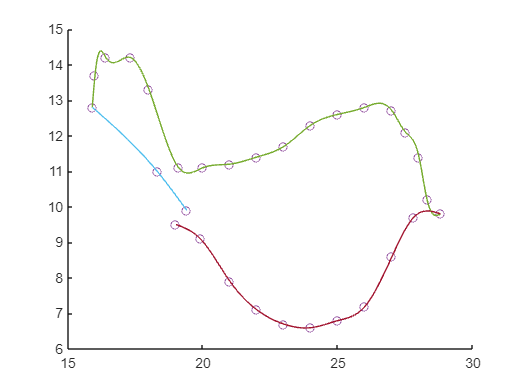

splin2 = splines(x2(1:3), y2(1:3));
range = [];
cubic = [];
for i = 1:2
    aux = x2(i):.01:x2(i+1);
    range = [range aux];
    cubic = [cubic polyval(flip(splin2((i-1)*4+1:i*4)), aux-x2(i))];
end
plot(range, cubic)

range = [];
cubic = [];
splin2 = splines(x2(4:14), y2(4:14));
for i = 4:13
    aux = x2(i):.01:x2(i+1);
    range = [range aux];
    cubic = [cubic polyval(flip(splin2((i-4)*4+1:(i-3)*4)), aux-x2(i))];
end
plot(range, cubic)


hold off

2. Use las siguientes ecuaciones diferenciales para calcular la velocidad y posición de un balón de fútbol que es pateado directo hacia arriba en el aire con una velocidad inicial de 40 𝑚/𝑠.


$$\frac{dy}{dt} = v$$



$$\frac{dv}{dt} = -g-\frac{c_d}{m}v|v|$$


Donde 𝑦 es la distancia hacia arriba (𝑚), 𝑡 es el tiempo (𝑠), 𝑣 es la velocidad hacia arriba (𝑚/𝑠), 𝑔 es la constante gravitacional (≈ 9.81 𝑚/𝑠 2 ), 𝑐𝑑 es el coeficiente de arrastre (𝑘𝑔/𝑚) y 𝑚 es la masa (𝑘𝑔). Observe que el coeficiente de arrastre se relaciona a más parámetros fundamentales por medio de


$$c_d=\frac{1}{2}\rho AC_d$$


Donde 𝜌 es la densidad del aire (𝑘𝑔/𝑚3 ), 𝐴 es el área (𝑚2 ) y 𝐶𝑑 es el coeficiente de arrastre adimensional. Para los parámetros, use los siguientes valores: 𝑑 = 22 𝑐𝑚, 𝑚 = 0.4 𝑘𝑔, 𝜌 = 1.3 𝑘𝑔/𝑚3 y 𝐶𝑑 = 0.52.

syms t
syms y
syms v
f1(t,y,v) = v

$$f1(t, y, v) = v$$

c = (1.3*(pi*0.11^2)*0.52)/2

c = 0.0128

f2(t,y,v) = -9.8-c/m*v*abs(v)

$$f2(t, y, v) = -\frac{2314577404659673\,v\,\left|v\right|}{72057594037927936}-\frac{49}{5}$$

[w,tv] = taylor_2v2y(f1, f2, 0, 0.005, 0, 40, 'RK4', 0)

w =          0    0.1992    0.3970    0.5932    0.7880    0.9813    1.1731    1.3636    1.5527    1.7403    1.9266    2.1116    2.2952    2.4775    2.6585    2.8382    3.0166    3.1937    3.3697    3.5443    3.7178    3.8901    4.0611    4.2310    4.3998    4.5673    4.7338    4.8991    5.0633    5.2263    5.3883    5.5492    5.7091    5.8678    6.0256    6.1822    6.3379    6.4925    6.6462    6.7988    6.9504    7.1011    7.2508    7.3995    7.5473    7.6942    7.8401    7.9851    8.1291    8.2723
   40.0000   39.6960   39.3958   39.0994   38.8067   38.5177   38.2322   37.9501   37.6715   37.3963   37.1243   36.8555   36.5900   36.3275   36.0680   35.8116   35.5581   35.3074   35.0596   34.8146   34.5723   34.3327   34.0956   33.8612   33.6293   33.3999   33.1730   32.9485   32.7263   32.5064   32.2888   32.0735   31.8604   31.6494   31.4406   31.2339   31.0293   30.8266   30.6260   30.4273   30.2306   30.0358   29.8428   29.6517   29.4624   29.2749   29.0891   28.9051   28.7227   28

tv =          0    0.0050    0.0100    0.0150    0.0200    0.0250    0.0300    0.0350    0.0400    0.0450    0.0500    0.0550    0.0600    0.0650    0.0700    0.0750    0.0800    0.0850    0.0900    0.0950    0.1000    0.1050    0.1100    0.1150    0.1200    0.1250    0.1300    0.1350    0.1400    0.1450    0.1500    0.1550    0.1600    0.1650    0.1700    0.1750    0.1800    0.1850    0.1900    0.1950    0.2000    0.2050    0.2100    0.2150    0.2200    0.2250    0.2300    0.2350    0.2400    0.2450


plot(tv, w)
legend('Posicion','Velocidad')

De modo que la altura maxima esta aproximadamente en 28.51165 metros